%impulse reference response
clc;
clear all;
close all;
num=1;
t=0:0.1:8;
p1 = 1;
p2 = 2;
p3 = 5;
den1=[1 p1 0];
den2=[1 p2 0];
den3=[1 p3 0];
y1=impulse(num,den1,t);
y2=impulse(num,den2,t);
y3=impulse(num,den3,t);
plot(t,y1,'r',t,y2,'b',t,y3,'g')

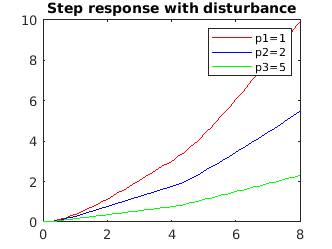

title('Impulse response')
legend('p1=1','p2=2','p3=5')
 
 
% step reference response
%PES1UG20EC083 JACOB V SANOJ
clc;
clear all;
close all;
num=1;
t=0:0.1:8;
p1 = 1;
p2 = 2;
p3 = 5;
den1=[1 p1 0];
den2=[1 p2 0];
den3=[1 p3 0];
y1=step(num,den1,t);
y2=step(num,den2,t);
y3=step(num,den3,t);
plot(t,y1,'r',t,y2,'b',t,y3,'g')
title('Step response')
legend('p1=1','p2=2','p3=5')
 
% step reference and a specified disturbance input
clc;
clear all;
close all;
t=0:0.1:8;
p1 = 1;
p2 = 2;
p3 = 5;
g1=tf([0 0 1],[1 p1 0]);
g2=tf([0 0 1],[1 p2 0]);
g3=tf([0 0 1],[1 p3 0]);
a1=step(g1,t);
a2=step(g2,t);
a3=step(g3,t);
d = 0*t;
d(t>=0 & t<=4)=1;
d(t>4 & t<=8)=2;
y1= lsim(g1,d,t);
y2= lsim(g2,d,t);
y3= lsim(g3,d,t);
plot(t,y1,'r',t,y2,'b',t,y3,'g')
title('Step response with disturbance')
legend('p1=1','p2=2','p3=5')